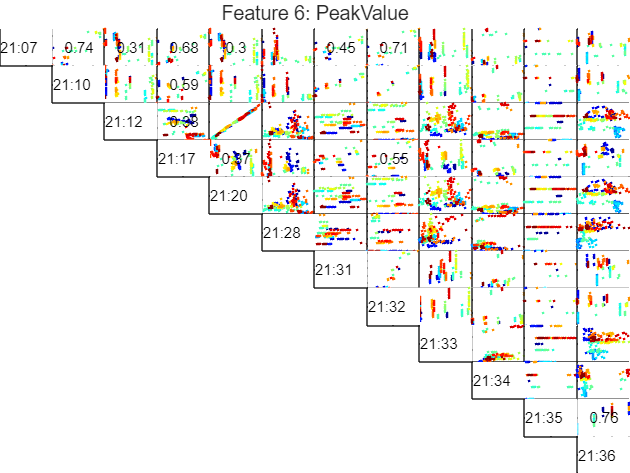

Features = DFD_FeatureTable_TimeDomain;
SignalNames = signalNames_Time;
FeatureNames = featureNames_Time;
lowerR2 = 0.3;
upperR2 = 0.8;
selectedFeature = 6; % Peak value
R2 = fnPlotSignalVsSignal(Features, lowerR2, upperR2, selectedFeature, FeatureNames, SignalNames, sensorNames);        

disp(num2str(R2, '%.2f  '));

0.00  0.74  0.31  0.68  0.30  0.03  0.45  0.71  0.01  0.00  0.00  0.02
0.00  0.00  0.18  0.59  0.18  0.00  0.82  0.99  0.11  0.06  0.00  0.00
0.00  0.00  0.00  0.38  0.99  0.00  0.01  0.17  0.00  0.00  0.15  0.05
0.00  0.00  0.00  0.00  0.37  0.00  0.30  0.55  0.00  0.02  0.09  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.01  0.17  0.00  0.00  0.15  0.05
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.04  0.04  0.22  0.26
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.82  0.13  0.11  0.02  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.13  0.07  0.00  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.21  0.03  0.04
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.76
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00


selectedSignal = 1; % row 1
[selectedSignalArray, selectedSignalData, numOfSelectedSignals] = fnSelectFeatures(selectedFeature, selectedSignal, featureArray, R2, upperR2, lowerR2);
disp(selectedSignalArray);

     1     2     3     4     5     7     8



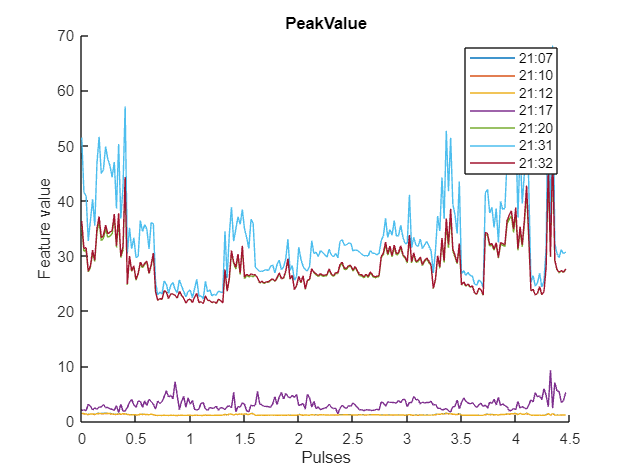

figure(); hold on;
leg = {numOfSelectedSignals};
for i = 1:numOfSelectedSignals
    plot(selectedSignalData{i});
    txtTemp = char(sensorNames(selectedSignalArray(i)));
    leg{i} = char(txtTemp(1:5));
end
title(FeatureNames(selectedFeature));
xlabel("Pulses");
ylabel("Feature value");
legend(leg);

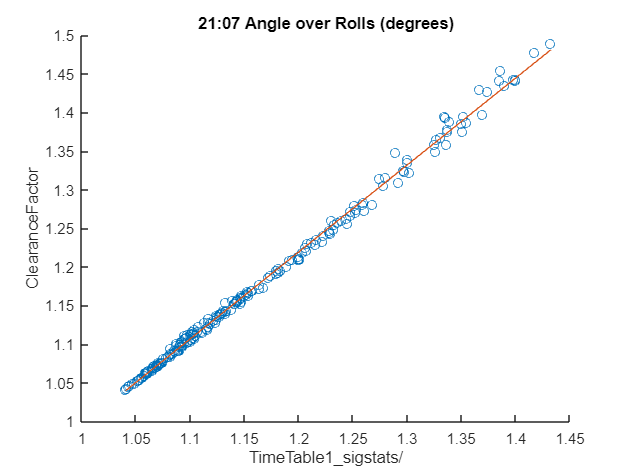

FIT = 94.37

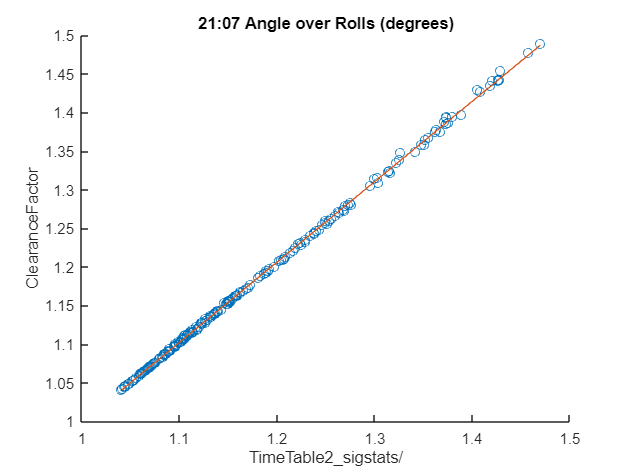

FIT = 98.03

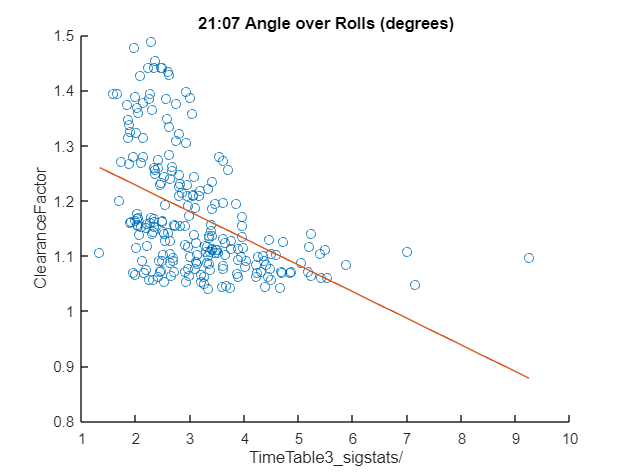

FIT = 11.49

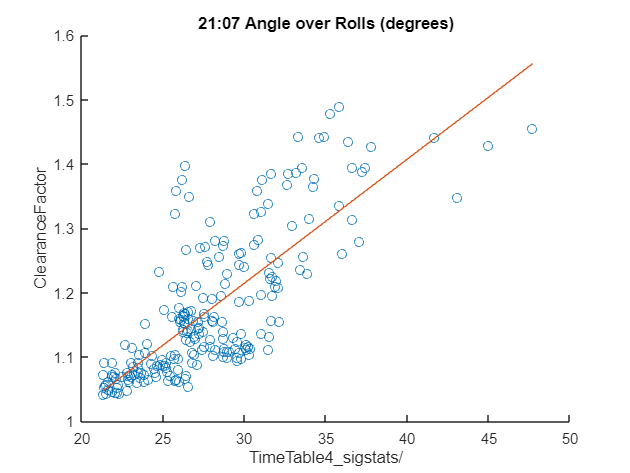

FIT = 36.48

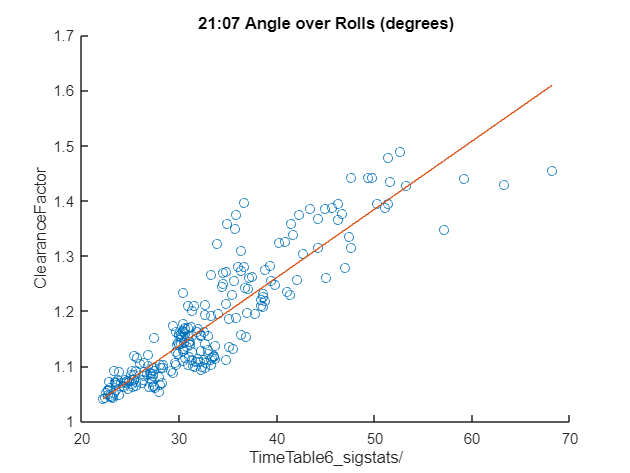

FIT = 57.21

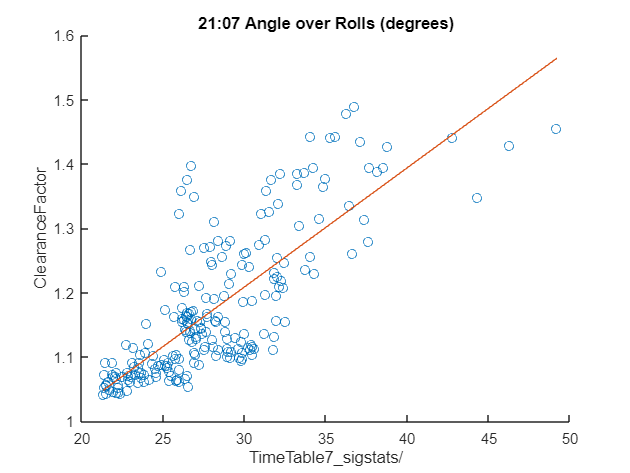

FIT = 37.57

for index = 1 : numOfSelectedSignals
    if index ~= selectedSignal
        fnPlotModel(selectedSignalData{selectedSignal}, selectedSignalData{index}, sensorNames(selectedSignal), FeatureNames(selectedSignalArray(selectedSignal)), SignalNames(selectedSignalArray(index)));
    end
end

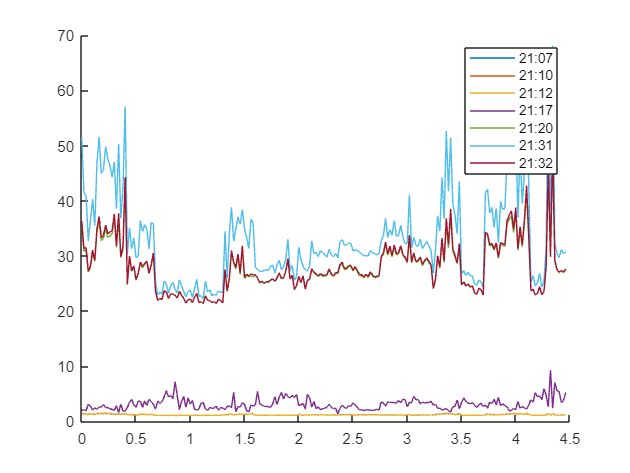

n = size(selectedSignalData{1}, 1);
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on
leg = {numOfSelectedSignals};
for i = 1:numOfSelectedSignals
    plot(t, selectedSignalData{i});
    txtTemp = char(sensorNames(selectedSignalArray(i)));
    leg{i} = char(txtTemp(1:5));
end
legend(leg);

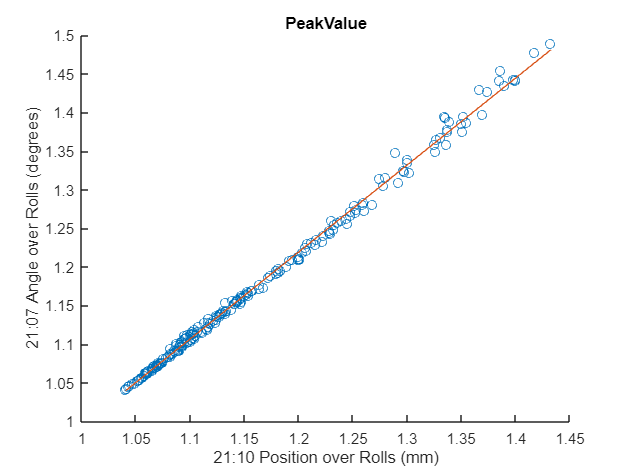

FIT = 94.37

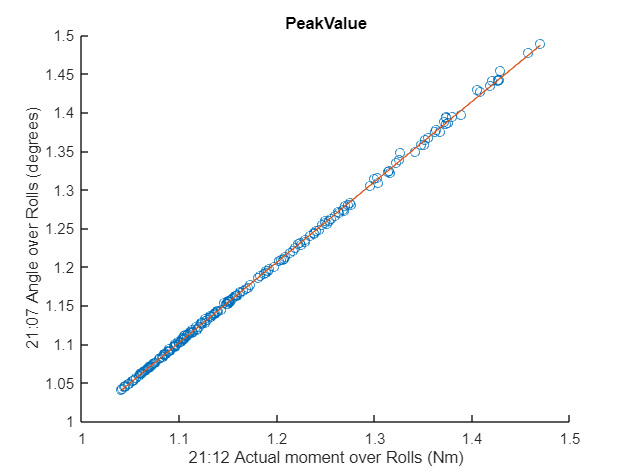

FIT = 98.03

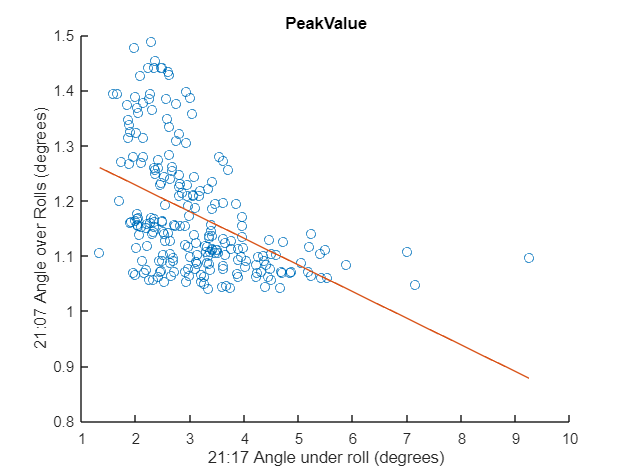

FIT = 11.49

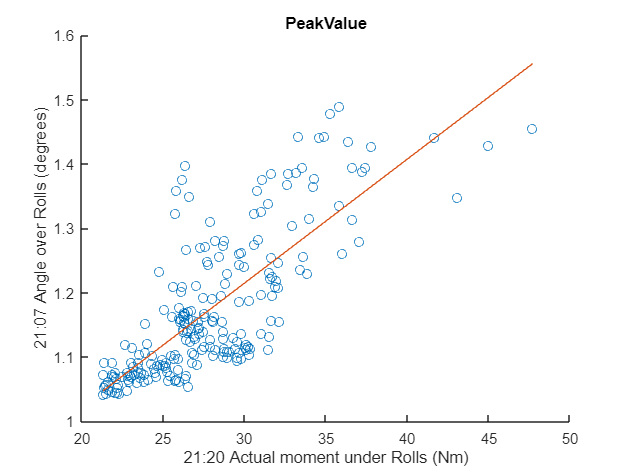

FIT = 36.48

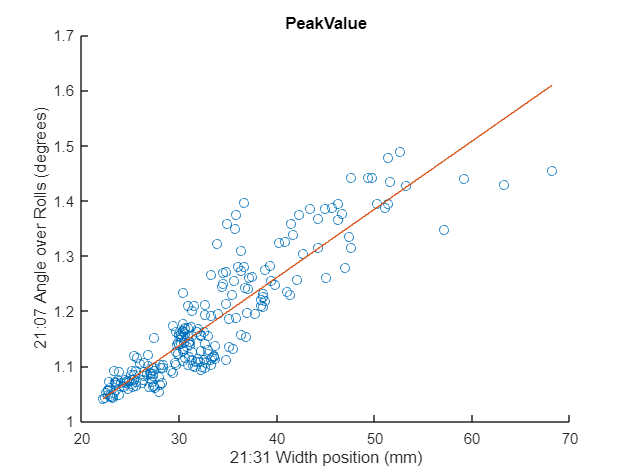

FIT = 57.21

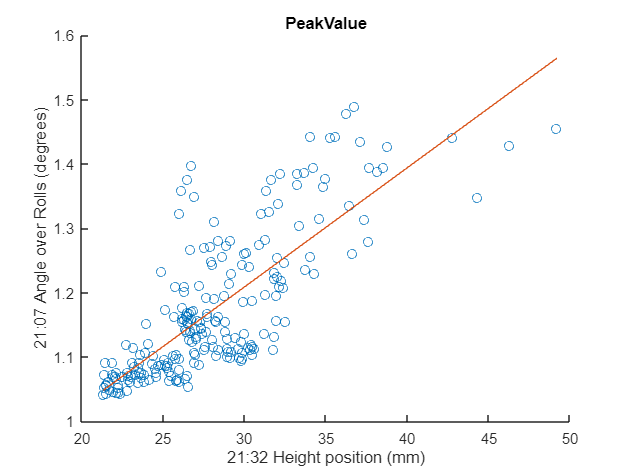

FIT = 37.57

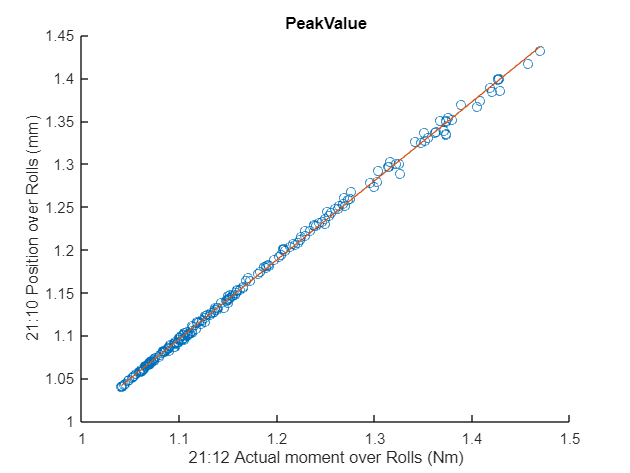

FIT = 96.32

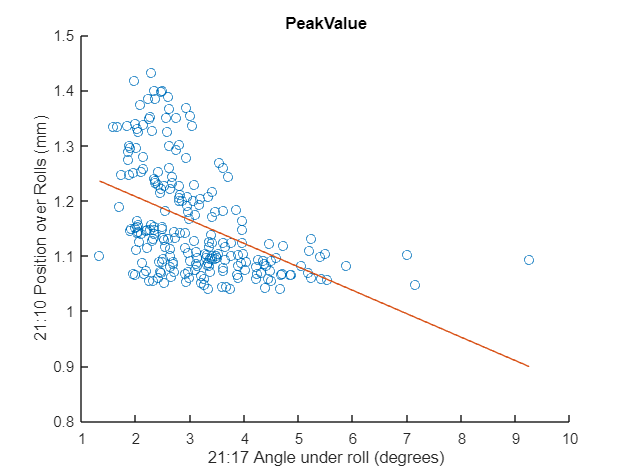

FIT = 11.34

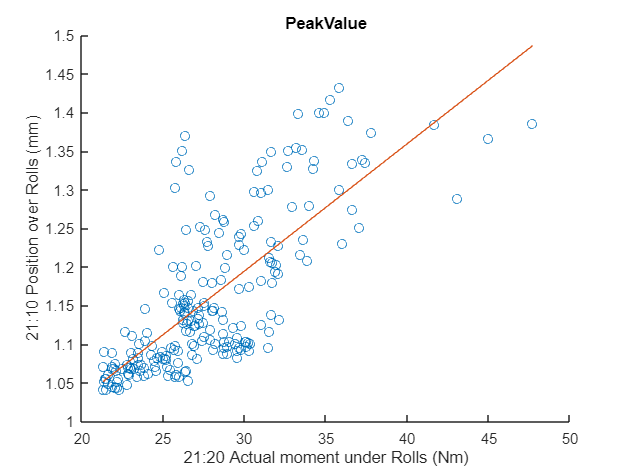

FIT = 33.41

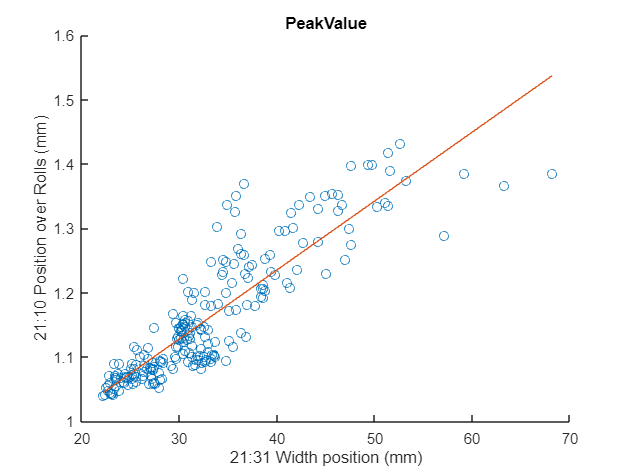

FIT = 53.29

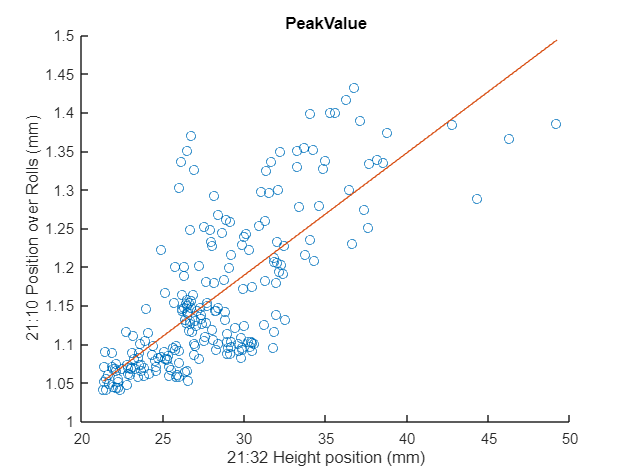

FIT = 34.39

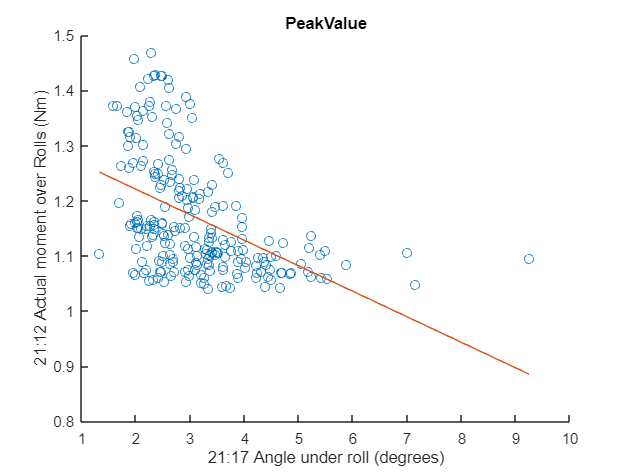

FIT = 11.46

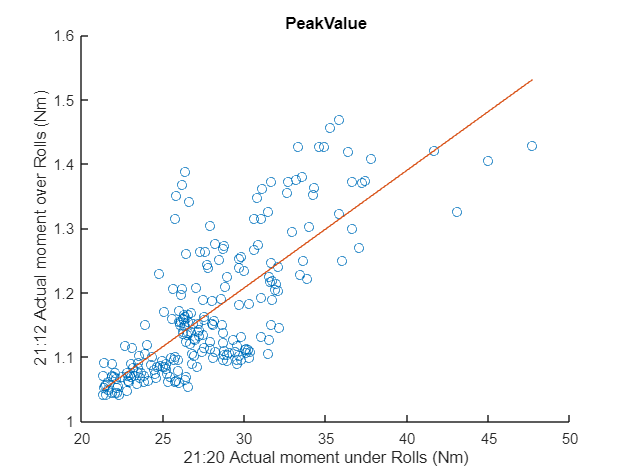

FIT = 35.37

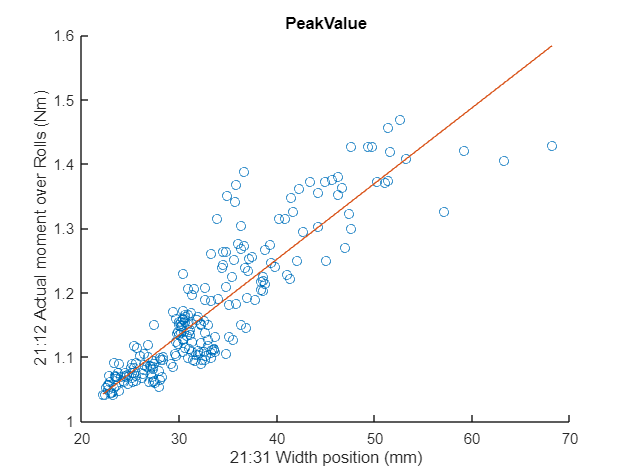

FIT = 55.81

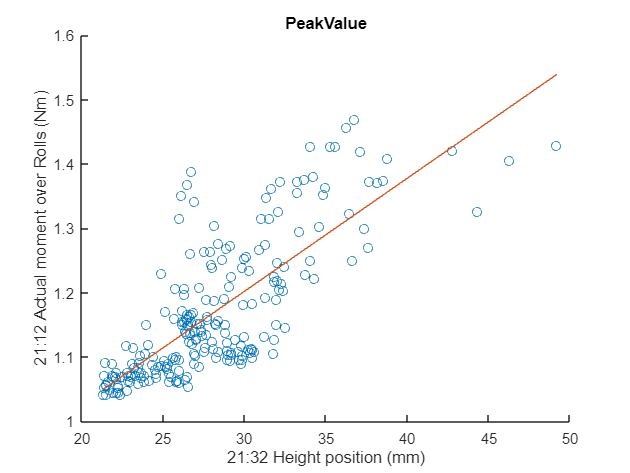

FIT = 36.42

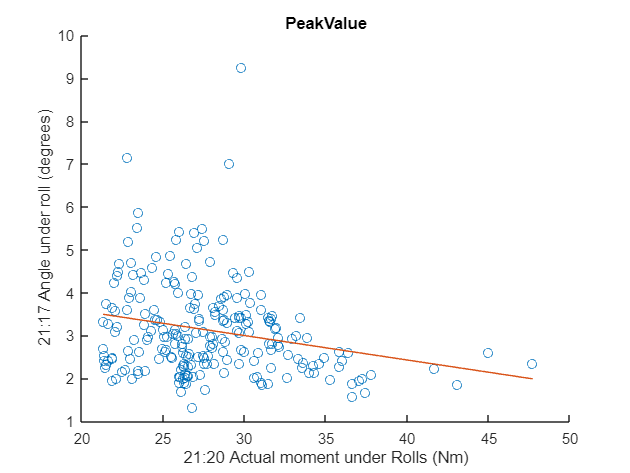

FIT = 2.85

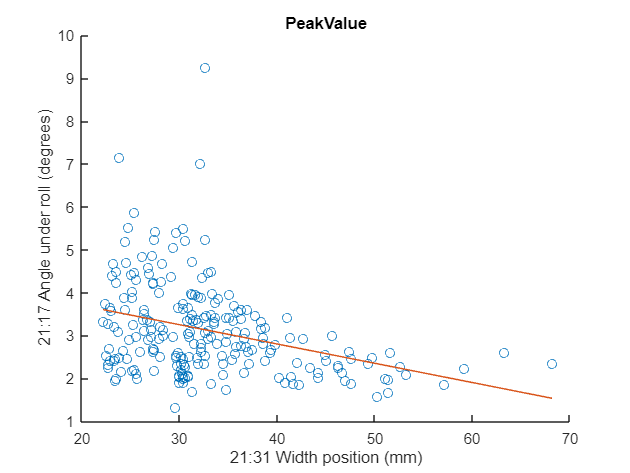

FIT = 6.00

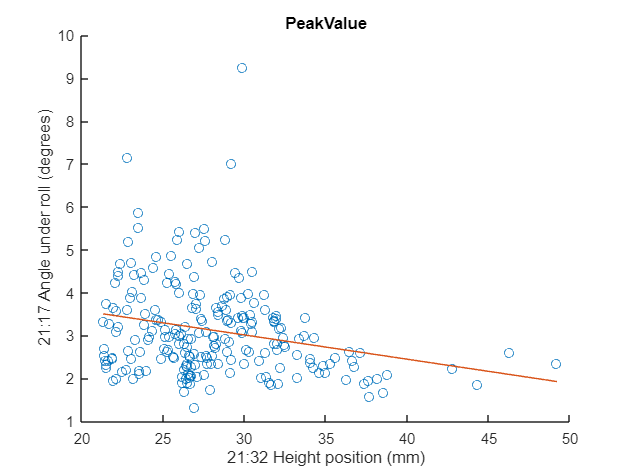

FIT = 3.12

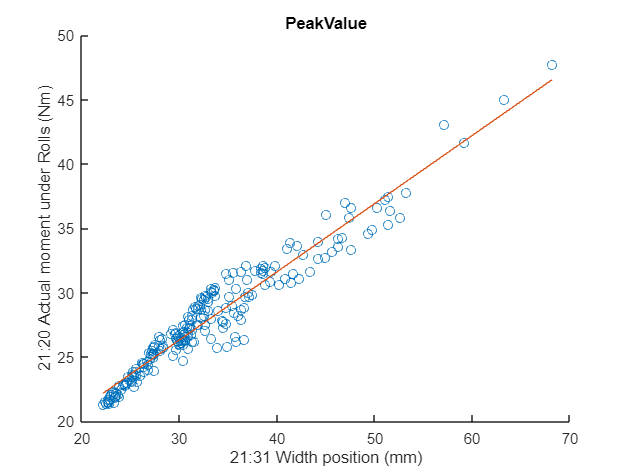

FIT = 74.38

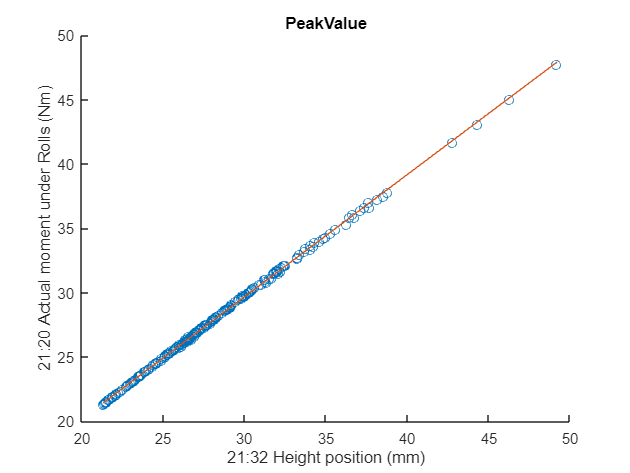

FIT = 97.74

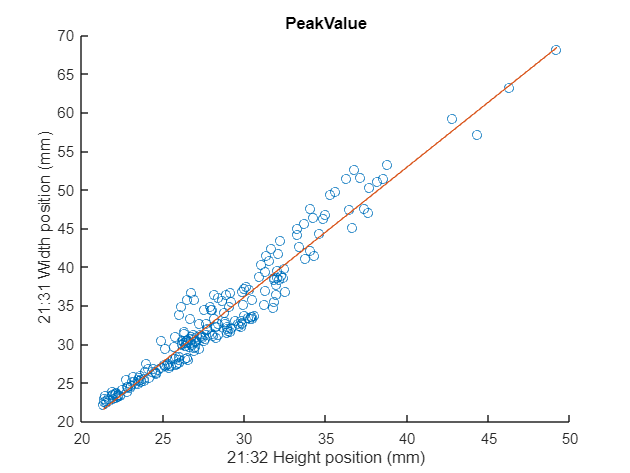

FIT = 75.99

for index1 = 1 : numOfSelectedSignals
    for index2 = index1 + 1 : numOfSelectedSignals
        fnPlotModel(selectedSignalData{index1}, ...
            selectedSignalData{index2}, ...
            FeatureNames(selectedFeature), ...
            sensorNames(selectedSignalArray(index1)), ...
            sensorNames(selectedSignalArray(index2)));
    end
end

1 2 3

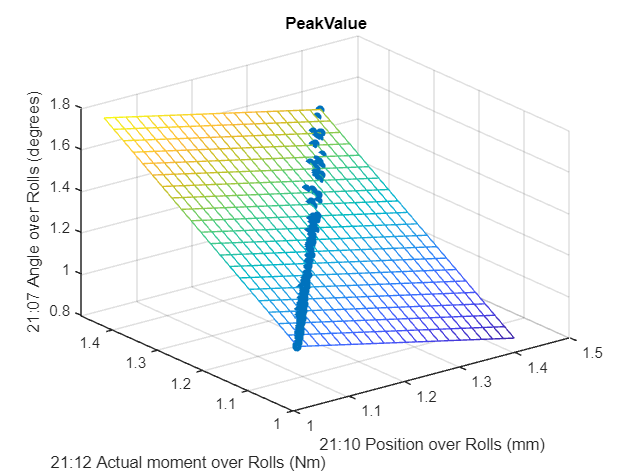

FIT = 99.757368

1 2 4

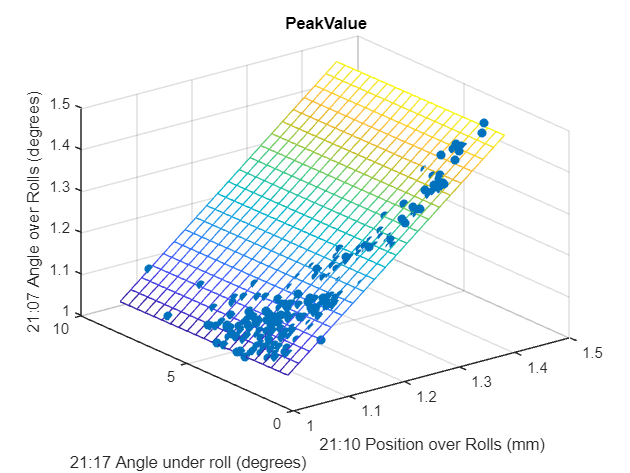

FIT = 94.382558

1 2 5

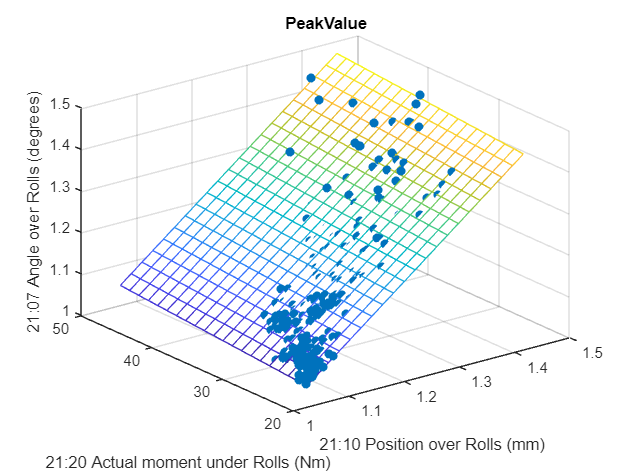

FIT = 96.156972

1 2 6

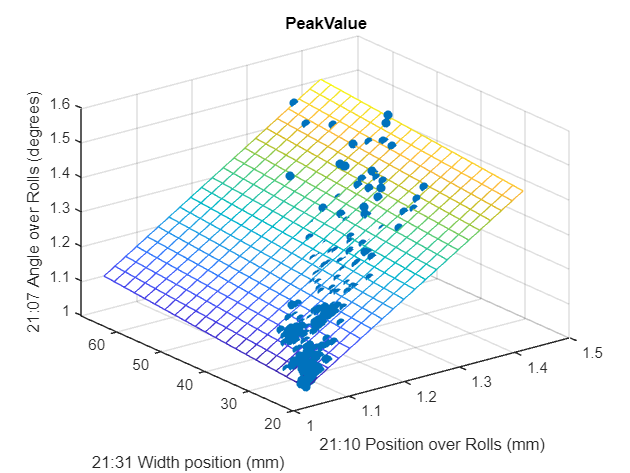

FIT = 96.614039

1 2 7

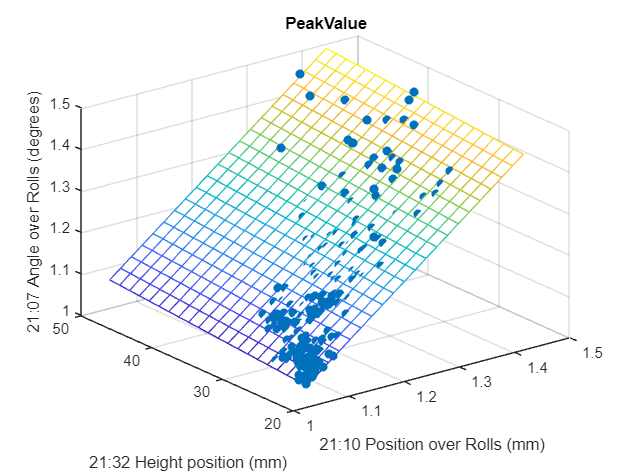

FIT = 96.268595

1 3 4

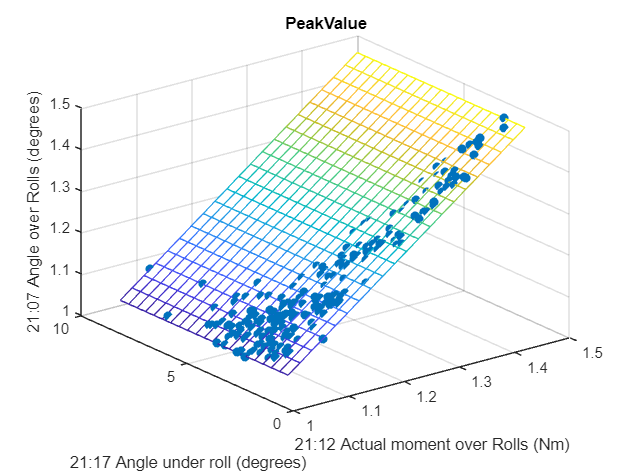

FIT = 98.033832

1 3 5

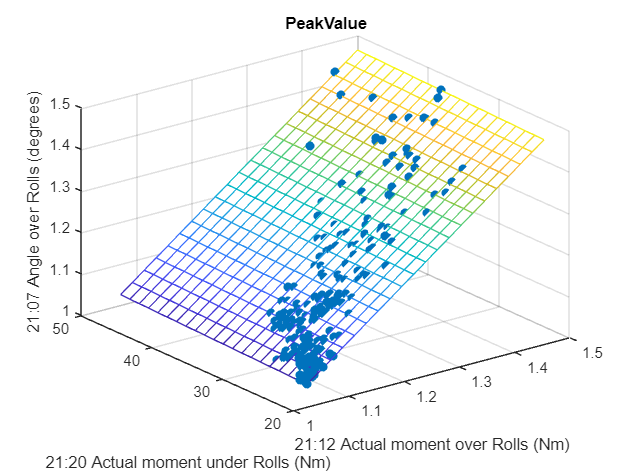

FIT = 98.668591

1 3 6

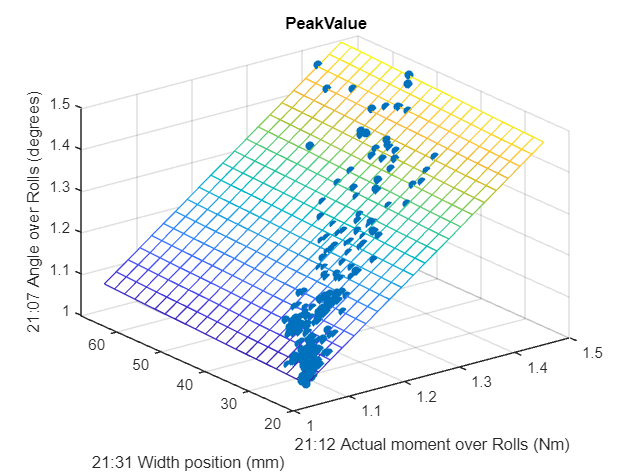

FIT = 98.815131

1 3 7

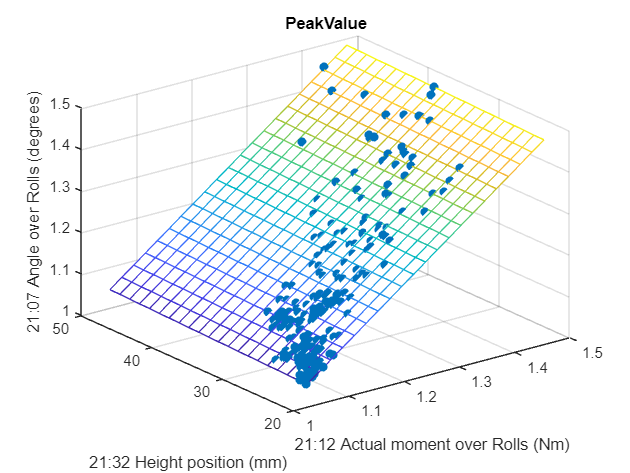

FIT = 98.708664

1 4 5

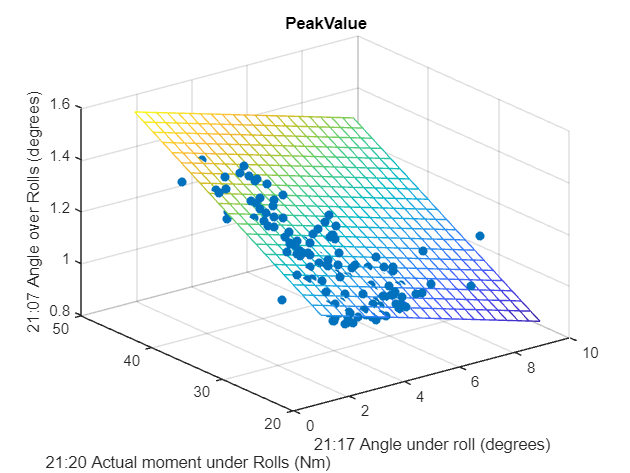

FIT = 43.511737

1 4 6

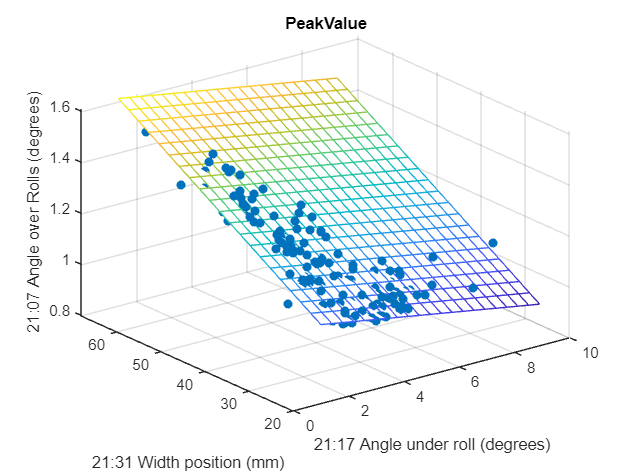

FIT = 60.613356

1 4 7

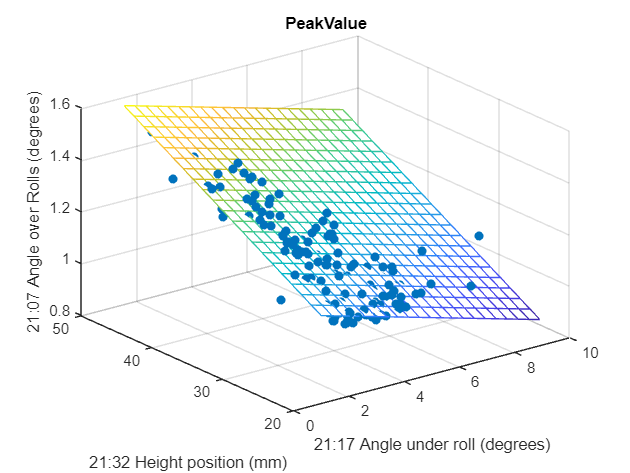

FIT = 44.232493

1 5 6

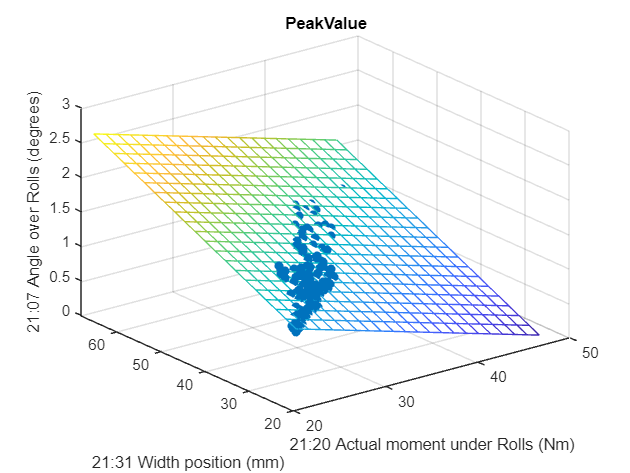

FIT = 83.689870

1 5 7

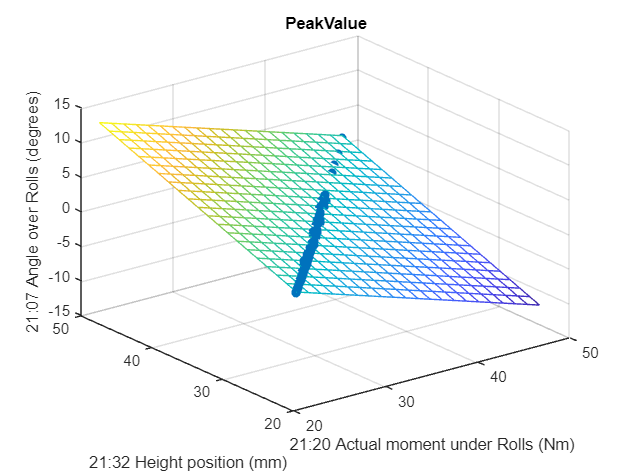

FIT = 50.663975

1 6 7

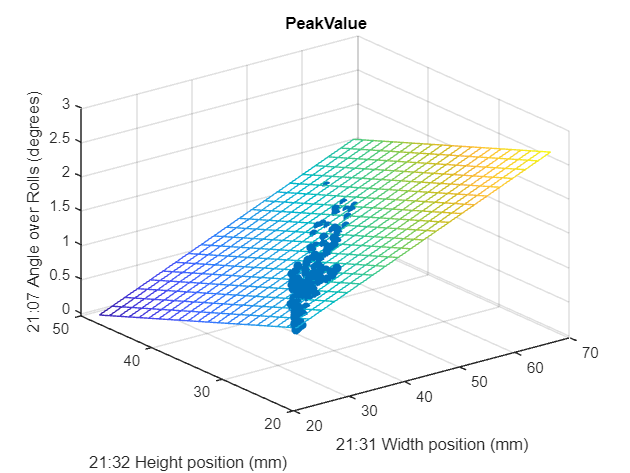

FIT = 85.026039

if numOfSelectedSignals > 2
    for index1 = 2 : numOfSelectedSignals
        for index2 = index1+1 : numOfSelectedSignals
            fprintf("%i %i %i", 1, index1, index2);
            Y_est = fnPlotModel3D( ...
                selectedSignalData{1}, ...
                selectedSignalData{index1}, ...
                selectedSignalData{index2}, ...
                FeatureNames(selectedFeature), ...
                sensorNames(selectedSignalArray(1)), ...
                sensorNames(selectedSignalArray(index1)), ...
                sensorNames(selectedSignalArray(index2)));
        end
    end
end